% OPTI 512L
% LAB 10
% Mohanbabu Mani


% 1.


function W = constructHaarDWTMatrix(N)

    if log2(N) ~= floor(log2(N))
        error('N must be a power of 2');
    end
    
    W = zeros(N, N);
    h_low = (1/sqrt(2)) * [1, 1];    
    h_high = (1/sqrt(2)) * [1, -1];   
   
    for k = 1:N/2
        idx1 = 2*k - 1;
        idx2 = 2*k;
        W(k, idx1) = h_high(1);
        W(k, idx2) = h_high(2);
        W(N/2 + k, idx1) = h_low(1);
        W(N/2 + k, idx2) = h_low(2);
    end
end


N = 8;  
W = constructHaarDWTMatrix(N);

disp('Generated Haar DWT Matrix W:');

Generated Haar DWT Matrix W:


disp(W);

    0.7071   -0.7071         0         0         0         0         0         0
         0         0    0.7071   -0.7071         0         0         0         0
         0         0         0         0    0.7071   -0.7071         0         0
         0         0         0         0         0         0    0.7071   -0.7071
    0.7071    0.7071         0         0         0         0         0         0
         0         0    0.7071    0.7071         0         0         0         0
         0         0         0         0    0.7071    0.7071         0         0
         0         0         0         0         0         0    0.7071    0.7071



disp(' ');


unitarity_check = W' * W;
disp('W^T * W:');

W^T * W:


disp(unitarity_check);

    1.0000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0    1.0000



disp(' ');


identity_matrix = eye(N);
unitarity_error = norm(unitarity_check - identity_matrix, 'fro');
fprintf('Norm of (W^T*W - I): %.2e\n\n', unitarity_error);

Norm of (W^T*W - I): 6.28e-16




f = zeros(N, 1);
f(2) = 1; 

fprintf('Original vector f:\n');

Original vector f:


disp(f');

     0     1     0     0     0     0     0     0



disp(' ');


w = W * f;
fprintf('DWT coefficients w:\n');

DWT coefficients w:


disp(w');

   -0.7071         0         0         0    0.7071         0         0         0



disp(' ');


W_inverse = W';
f_reconstructed = W_inverse * w;

fprintf('Reconstructed vector f_reconstructed:\n');

Reconstructed vector f_reconstructed:


disp(f_reconstructed');

         0    1.0000         0         0         0         0         0         0



disp(' ');


reconstruction_error = norm(f - f_reconstructed);
fprintf('Reconstruction Error: %.2e\n\n', reconstruction_error);

Reconstruction Error: 2.22e-16




disp('W is unitary, W^(-1) = W^T:');

W is unitary, W^(-1) = W^T:


disp(W_inverse);

    0.7071         0         0         0    0.7071         0         0         0
   -0.7071         0         0         0    0.7071         0         0         0
         0    0.7071         0         0         0    0.7071         0         0
         0   -0.7071         0         0         0    0.7071         0         0
         0         0    0.7071         0         0         0    0.7071         0
         0         0   -0.7071         0         0         0    0.7071         0
         0         0         0    0.7071         0         0         0    0.7071
         0         0         0   -0.7071         0         0         0    0.7071



disp(' ');


f_random = randn(N, 1);
w_random = W * f_random;
f_random_reconstructed = W_inverse * w_random;
random_error = norm(f_random - f_random_reconstructed);

fprintf('Random vector reconstruction error: %.2e\n', random_error);

Random vector reconstruction error: 7.87e-16


disp(' ');

% 2.


img = imread('santa.JPG');

if length(size(img)) == 3
    img = rgb2gray(img);
end

img = double(img);

[rows, cols] = size(img);
N = 2^floor(log2(min(rows, cols)));
img = imresize(img, [N, N]);

fprintf('Resized to: %d x %d\n', N, N);

Resized to: 512 x 512


fprintf('Image data range: [%.1f, %.1f]\n\n', min(img(:)), max(img(:)));

Image data range: [-6.6, 264.3]




W = constructHaarDWTMatrix(N);
img_dwt = W * img * W';

threshold = 0.1 * max(abs(img_dwt(:)));  
fprintf('Threshold value: %.2f\n', threshold);

Threshold value: 51.77



total_coeffs = N * N;
nonzero_before = sum(abs(img_dwt(:)) > 1e-10);
img_dwt_compressed = img_dwt;
img_dwt_compressed(abs(img_dwt_compressed) < threshold) = 0;
nonzero_after = sum(abs(img_dwt_compressed(:)) > 1e-10);
compression_ratio = (1 - nonzero_after/total_coeffs) * 100;

fprintf('Coefficients before compression: %d\n', nonzero_before);

Coefficients before compression: 174273


fprintf('Coefficients after compression:  %d\n', nonzero_after);

Coefficients after compression:  66726


fprintf('Compression ratio: %.2f%%\n\n', compression_ratio);

Compression ratio: 74.55%




W_inv = W';
img_reconstructed = W_inv * img_dwt_compressed * W;

correlation = corr2(img, img_reconstructed);
fprintf('Correlation: %.4f\n\n', correlation);

Correlation: 0.9976



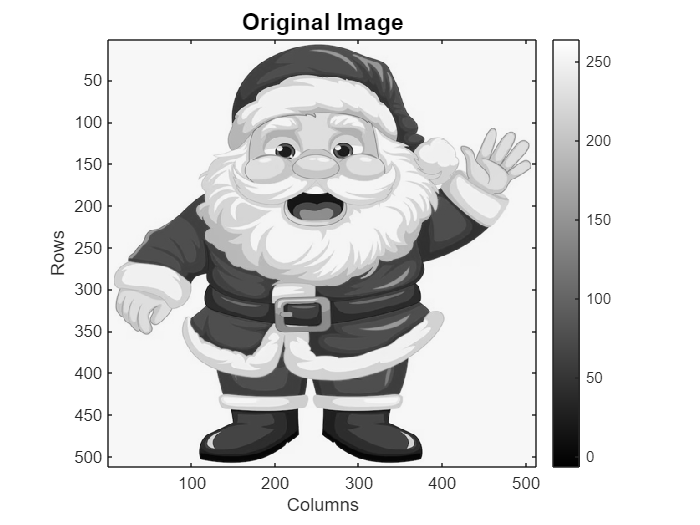


figure;
imagesc(img);
colormap(gray);
axis image;
title('Original Image', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Columns');
ylabel('Rows');
colorbar;

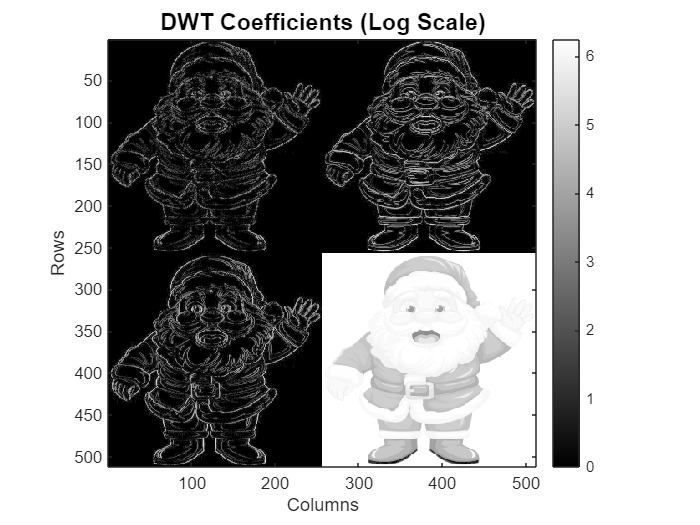


figure;
img_dwt_log = log(abs(img_dwt) + 1);
imagesc(img_dwt_log);
colormap(gray);
axis image;
title('DWT Coefficients (Log Scale)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Columns');
ylabel('Rows');
colorbar;

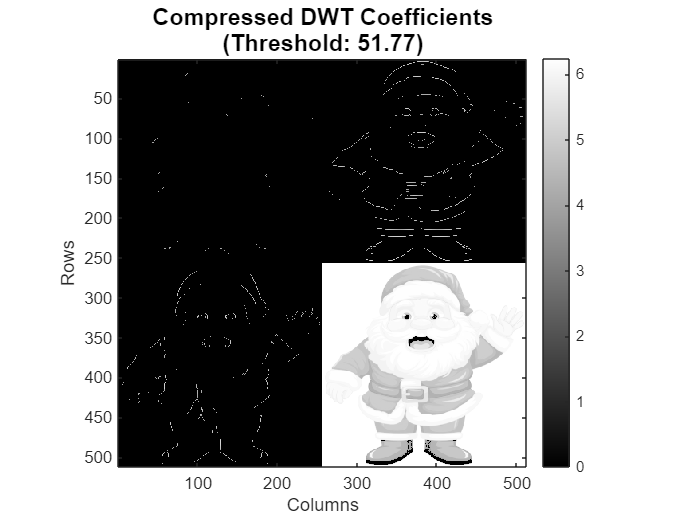


figure;
img_dwt_comp_log = log(abs(img_dwt_compressed) + 1);
imagesc(img_dwt_comp_log);
colormap(gray);
axis image;
title(sprintf('Compressed DWT Coefficients\n(Threshold: %.2f)', threshold), ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Columns');
ylabel('Rows');
colorbar;

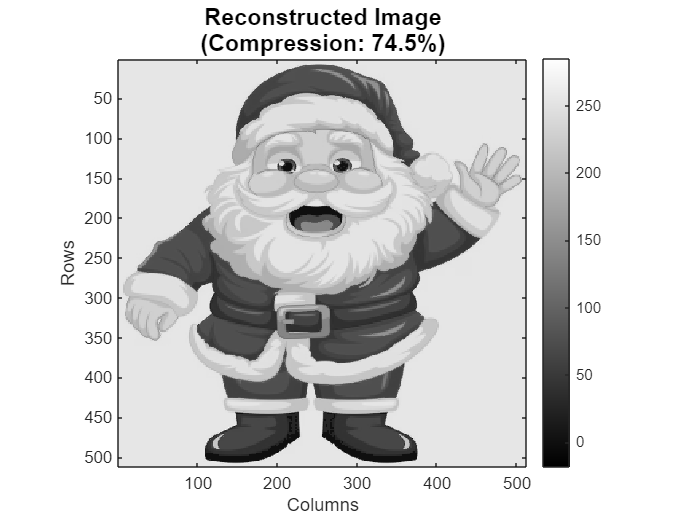


figure;
imagesc(img_reconstructed);
colormap(gray);
axis image;
title(sprintf('Reconstructed Image\n(Compression: %.1f%%)', compression_ratio), ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Columns');
ylabel('Rows');
colorbar;

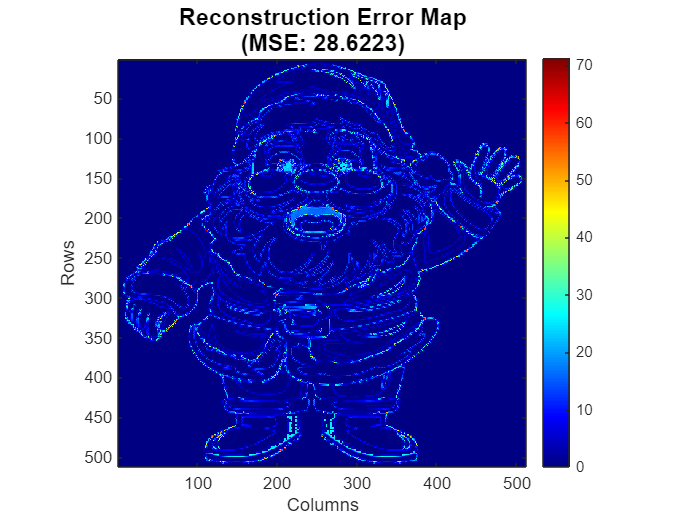


figure;
error_map = abs(img - img_reconstructed);
imagesc(error_map);
colormap(jet);
axis image;
title(sprintf('Reconstruction Error Map\n(MSE: %.4f)', mse), ...
    'FontSize', 14, 'FontWeight', 'bold');
xlabel('Columns');
ylabel('Rows');
colorbar;